clear, close all, clc


- Normal distribution is a bell shaped, symmetrical distributions. It is presented by the letter Z as defined below.


$$Z=\frac{X-\mu }{\sigma }$$
 

X represents a random varible from a normal distribution. Based on that, $\sigma$ represents the standard deviation of the curve, and $\mu$ represents the mean. It is commonly used to model things like a grade distribution of a class. 

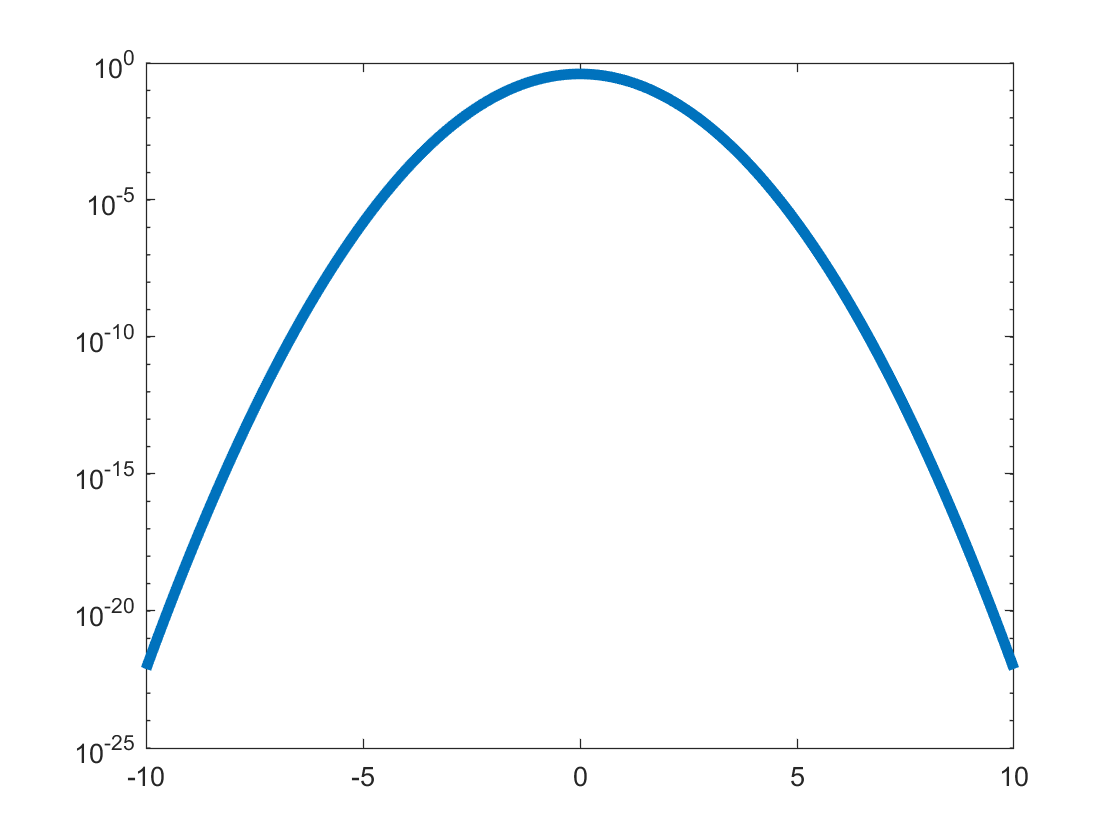

x = linspace(-10,10,1000);
sig = 1;
mu = 0;
gaus = makedist("Normal",mu,sig); 
semilogy(x,pdf(gaus,x),"LineWidth",4);

Here I plotted the integration of the gaussian curve without a log y-axis.

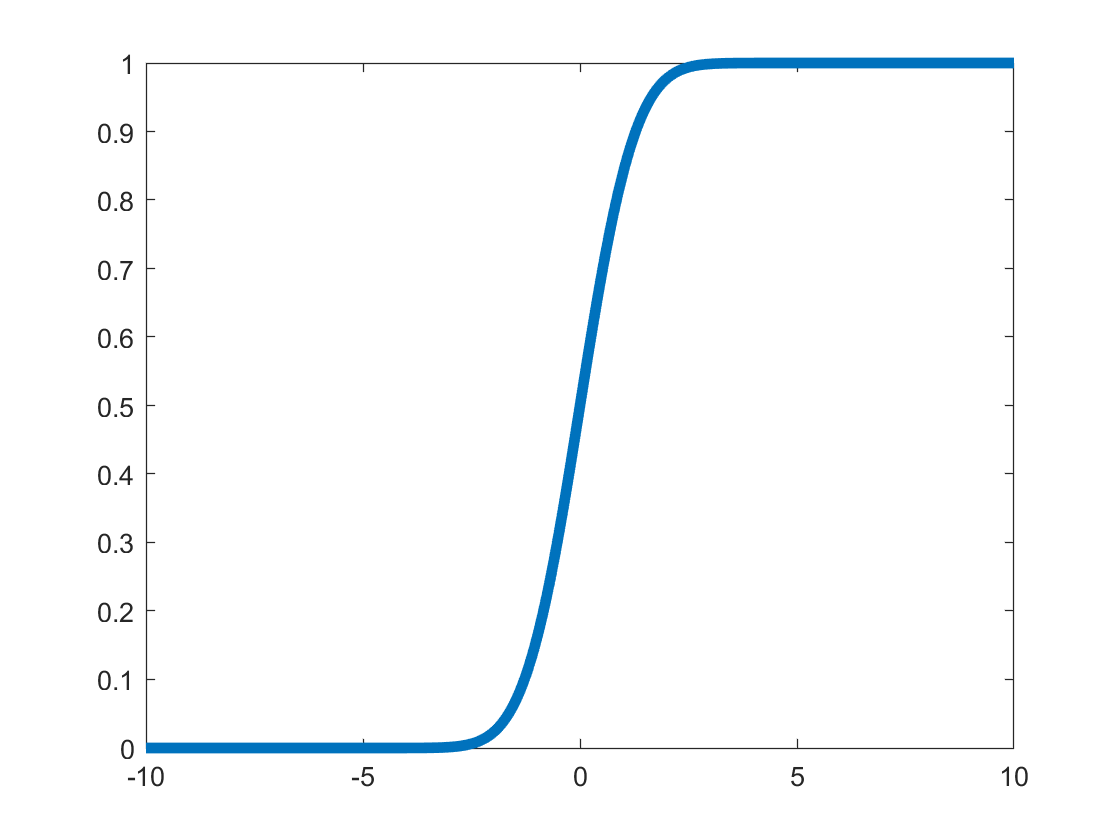



Norm_Int = normcdf(x,mu, sig);
plot(x,Norm_Int, "LineWidth",4)


Ztable_check = normcdf(0.2, mu, sig)

Ztable_check = 0.5793

When checking the cumulative Z-value table for 0.2, they match at 0.5793

Here I am using $p=\frac{1}{\sigma \sqrt{2\pi }}\int_{-\infty }^x e^{-\frac{{\left(t-\mu \right)}^2 }{2\sigma^2 }} \textrm{dt}$

sig_val = norminv(Norm_Int, mu, sig);
Sig = 3

Sig = 3


if Sig > 0 
    Percent_within_sig = Norm_Int(Sig*sig*50+500)
else
    Percent_within_sig = 1-Norm_Int(Sig*sig*50+500)
end

Percent_within_sig = 0.9986

Since I am integrating from -infinity my probabilities will vary from 0% up to 50% at the mean and then up to 100% at infinity. The specific probability values for sigma are close to what the tabulated values are, 1 sigma equates to a 83.92% (tabulate values is roughly 68%), 2 sigma equates to a 97.68% probability (tabulated value is roughly 95%), and 3 sigma equates to a probability of 99.86% (tabulated value is 99.7%).

2. Rayleigh distributions are often used to model background radiation in MRI scans. They allow for the estimation of noise variance in the MRI imagery. The formula for probability density function of a rayleigh distribution is 

$f\left(x:\sigma \right)=\frac{x}{\sigma^2 }e^{-\frac{x^2 }{2\sigma^2 }}$ where $\sigma$ is a scale parameter. 

x = linspace(0,10,100000);
sig =2

sig = 2

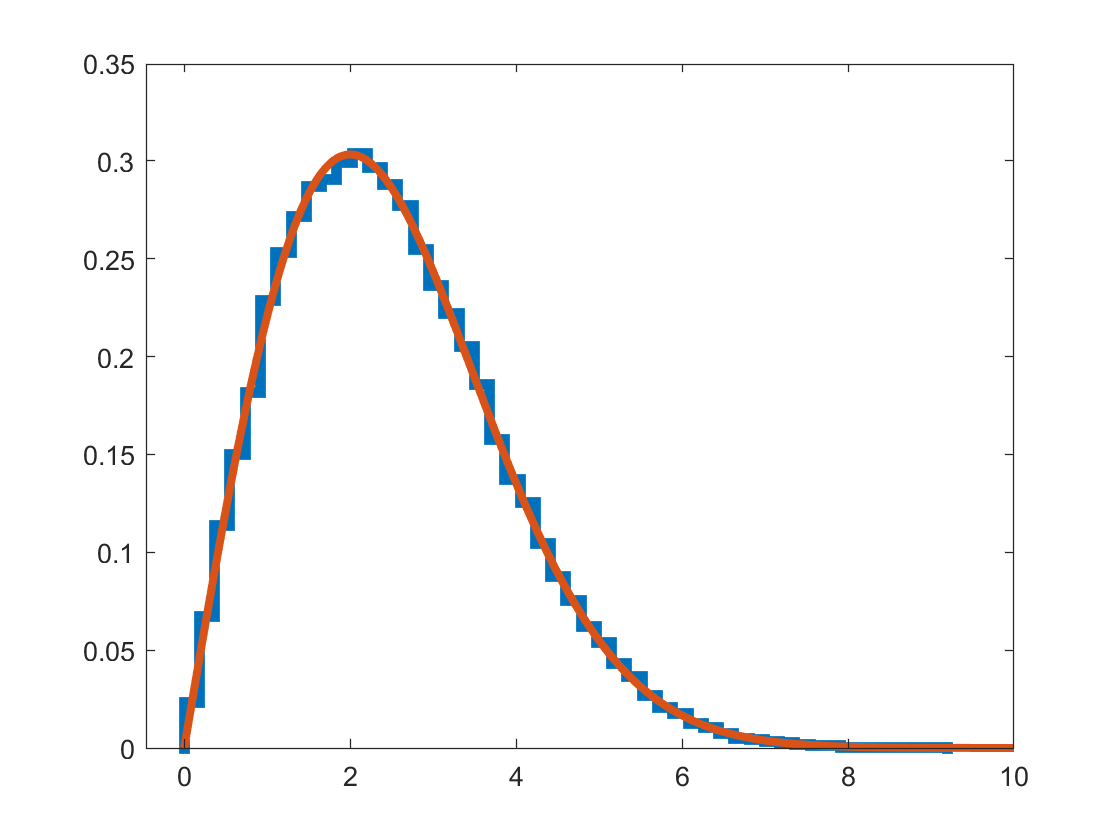

d = random('Rayleigh', sig, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',4,"Normalization","pdf")
hold on 
rayl = makedist("Rayleigh",sig);
semilogy(x,pdf(rayl,x),"LineWidth",3);
hold off

3. I will assume that this Rayleigh distribution is modeling a particularly hard final for a class. We'll assume that student A got a score of 3/10. We will find the sigma or standard deviation of student A's score and probability that student B will get a better score then student A. 

y_rayl_vals = pdf(rayl,x);
sum_rayl = 0;
for k = 1:length(y_rayl_vals)
    sum_rayl = y_rayl_vals(k)*x(k) + sum_rayl;
end
mean_rayl = sum_rayl/sum(y_rayl_vals, 'all')

mean_rayl = 2.5066

hyp = 3;
if mean_rayl<hyp
   sig_hyp = (hyp-mean_rayl)/sig
else
    sig_hyp = -(mean_rayl-hyp)/sig
end

sig_hyp = 0.2467

prob = 1 - cdf(rayl, hyp)

prob = 0.3247


hyp2 = 9.5

hyp2 = 9.5000

if mean_rayl<hyp2
   sig_hyp2 = (hyp2-mean_rayl)/sig
else
    sig_hyp = -(mean_rayl-hyp2)/sig
end

sig_hyp2 = 3.4967

prob2 = 1 - cdf(rayl, hyp2)

prob2 = 1.2607e-05


hyp3 = 0.2

hyp3 = 0.2000

if mean_rayl<hyp3
   sig_hyp3 = (hyp3-mean_rayl)/sig
else
    sig_hyp3 = -(mean_rayl-hyp3)/sig
end

sig_hyp3 = -1.1533

prob = 1 - cdf(rayl, hyp3)

prob = 0.9950

Choosing different values for the hypothetical value, in this case Student C got a 9.5/10 and Student D got a 0.2/10. The trend is the better the students score is above the mean value, the lower the liklihood that another student got a better score. The lower the students score is from the mean value, the more likely that another student got a better score as can be seen in the respective probabilities.

The Poisson distribution is a quantized varient of the Gaussian distribution in a vagues sense. The main difference is that the Poisson distribution is qunatized meaning meansuraments are integers rather then floats. It could be used to measure how many times some event occurs in a given time frame. 

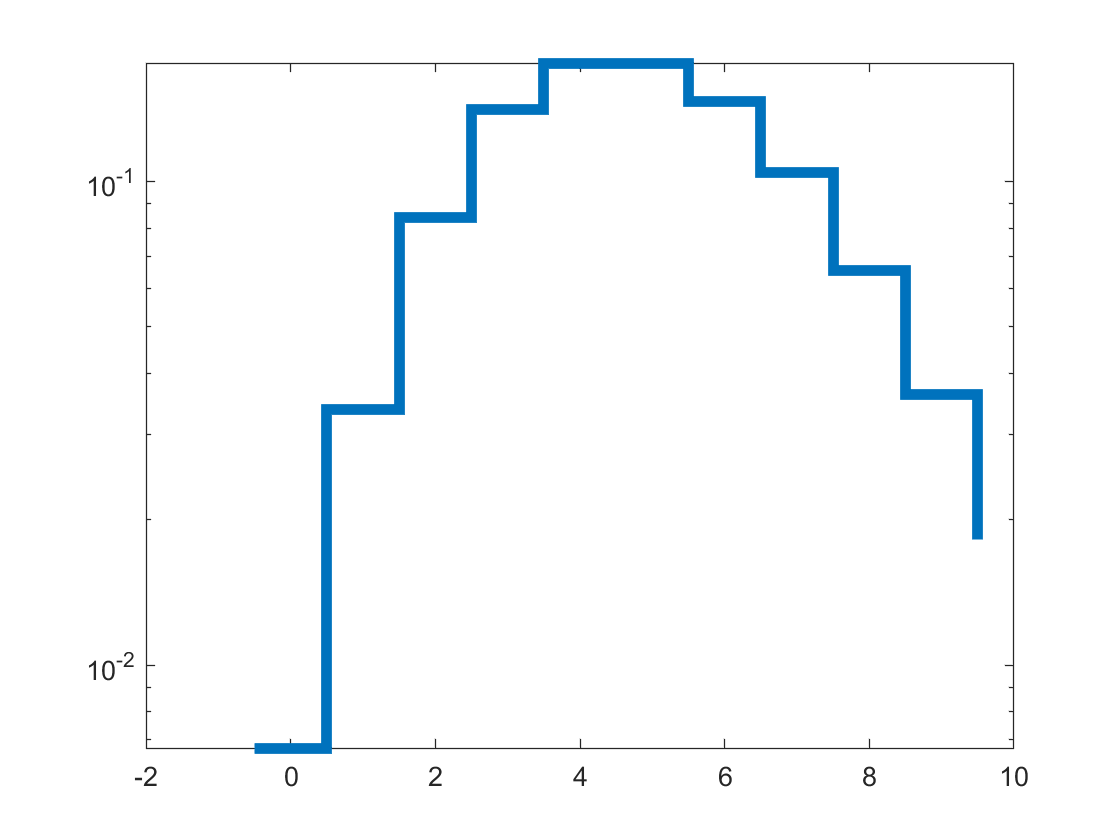


x = 0:10;
poisson = makedist("Poisson", 'lambda',5); 
%nu=1 makes a lorentz distribution as a special case
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

This plot exhibits a gaussian like shape aside from the stair step apperance. 

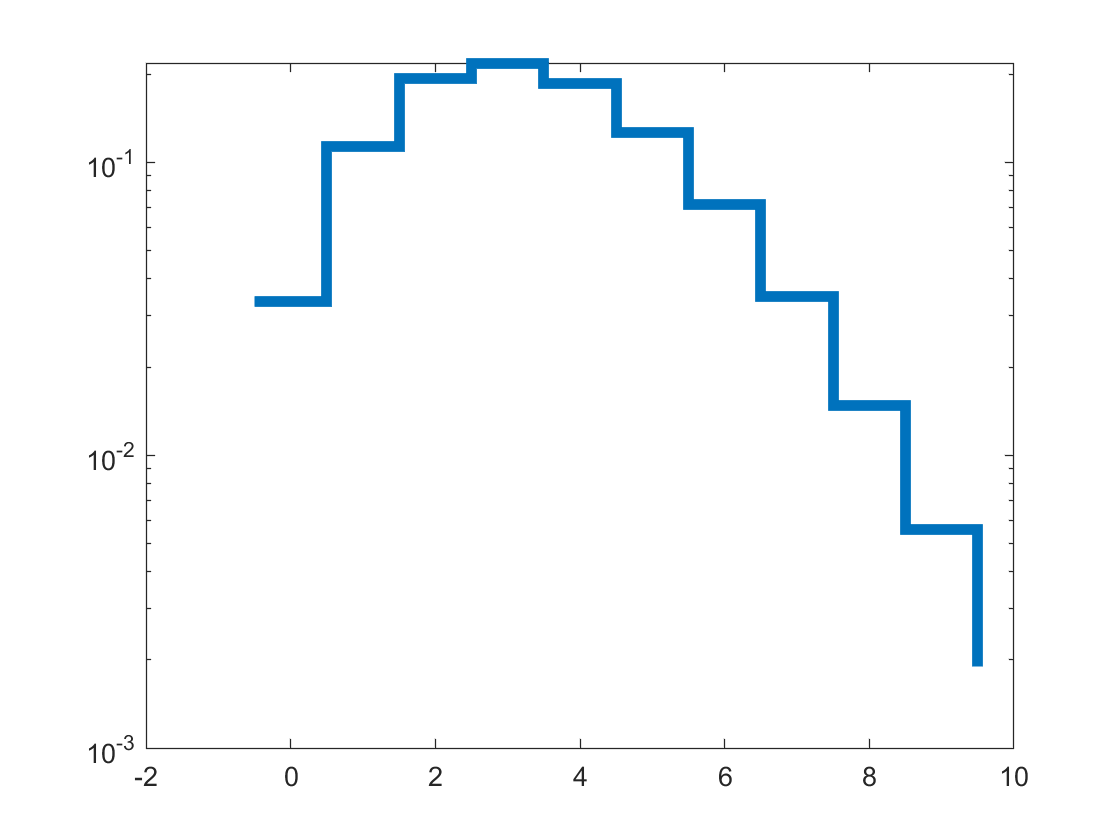


poisson = makedist("Poisson", 'lambda',3.4); 
%nu=1 makes a lorentz distribution as a special case
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

As the mean of the plot gets closer to zero it becomes more apparent that this is not a gaussian distribution as there is a non-zero values for a 0 number of occurances, even with a large number of samples. 

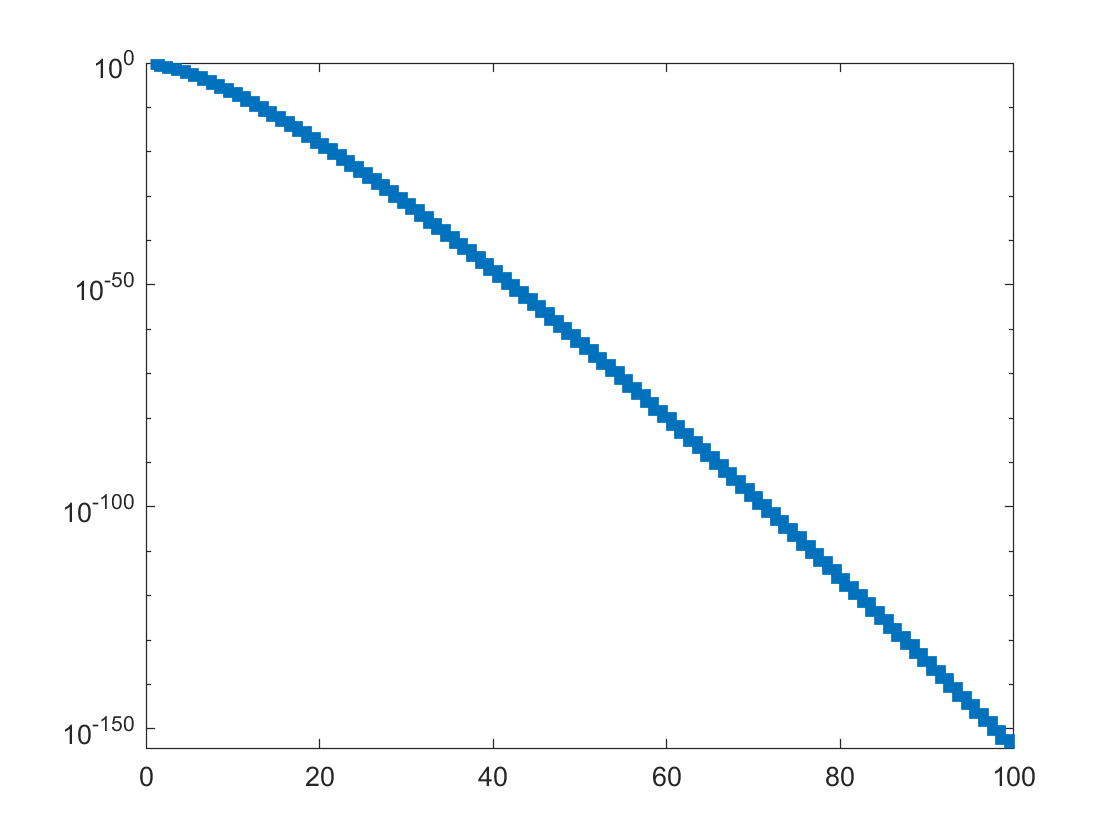

x=1:100;
poisson = makedist("Poisson", 'lambda',1.1); 
%nu=1 makes a lorentz distribution as a special case
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')

This is the more extreme case to the other two plots but it can be obviously seen that there is a non-zero value at  0 number of occurance.

We will try to measure the number of occurances a sample of uranium will give off an alpha particle. We will use a geiger counter to measure the number of alpha particles given off in a given time frame. We will specifically measure the probability that we got a value of 215 occurances in one minute

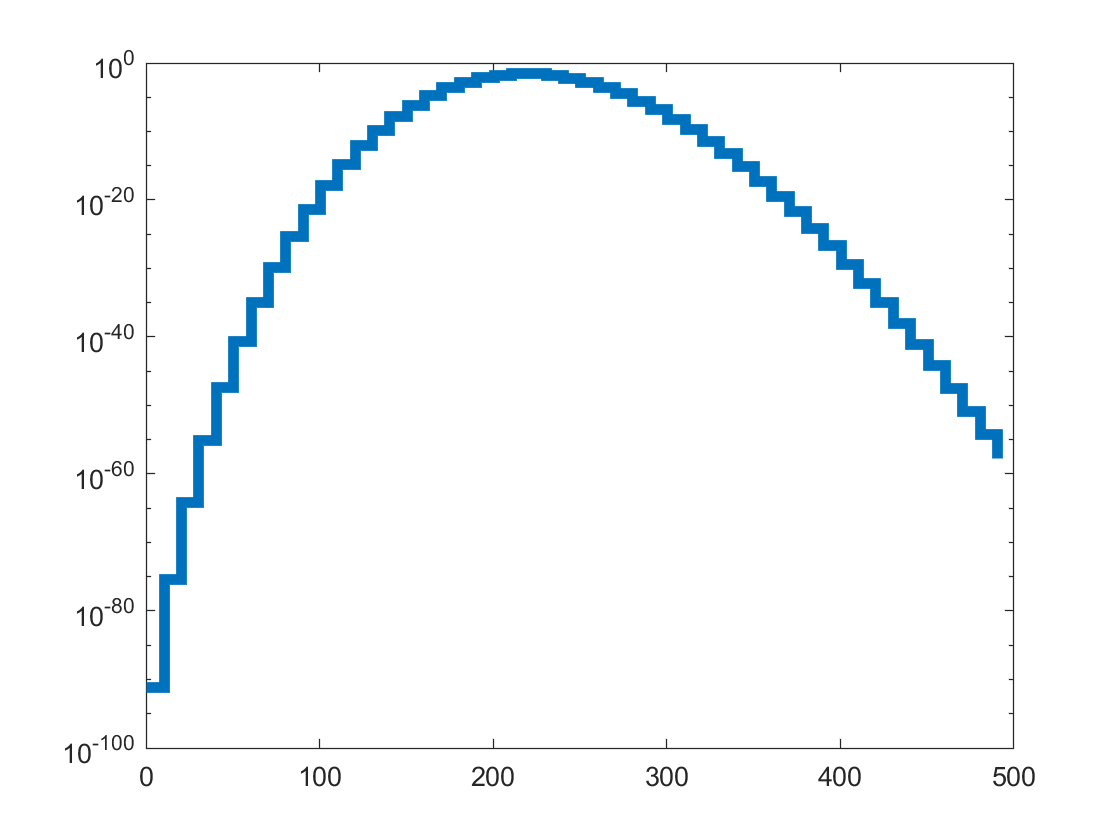

x = 1:10:500;
hyp = 215;
poisson = makedist("Poisson", 'lambda',215.3); 
%nu=1 makes a lorentz distribution as a special case
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);
set(gca,'YScale','log')


y_pois_vals = pdf(poisson,x);
sum_pois = 0;
for k = 1:length(y_pois_vals)
    sum_pois = y_pois_vals(k)*x(k) + sum_pois;
end

mean_pois = sum_pois/sum(y_pois_vals, 'all')

mean_pois = 215.3000


prob = 1 - cdf(poisson, hyp)

prob = 0.4900

Since there is only a certain number of times you can count an event happening the count is obviously a quantized integer, meaning you can count that 215 alpha particles hit the geiger counter in a minute. However, you can say there is a 49.38342923% chance that there will be 215 alpha particles hitting a geiger counter.